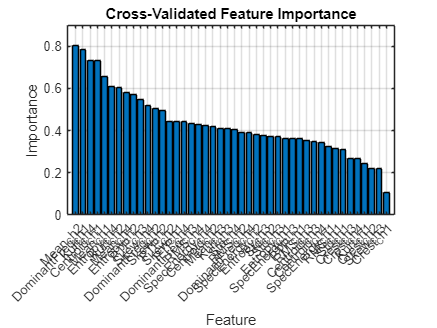

clear;

% Load dataset
datasetName = "dataset15";
files = metadata.selectPreset(metadata.collect('DataSet/Faulty bearing'), datasetName);

%pipeline_opt.exclude = ["Mean_A", "Mean_B", "Std_A", "Std_B", "Crest_A", "Crest_B"];
[X, Y, featureTbl, featureNames] = features.pipeline(files);

rfM = ml.rfMetrics(X, Y, featureNames);

% Plot Feature Importance Bar
figure;
bar(rfM.featureImp);
title('Cross-Validated Feature Importance');
xlabel('Feature');
ylabel('Importance');
xticks(1:length(rfM.featureNames));
xticklabels(rfM.featureNames);
xtickangle(45);
grid on;

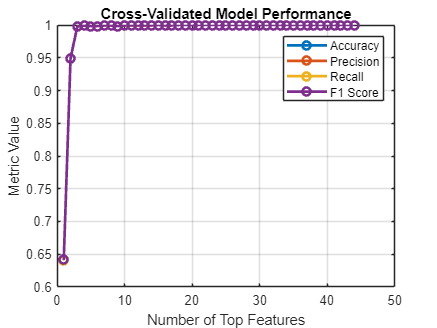


% Plot Metrics vs. Number of Features
figure;
plot(rfM.metrics, '-o', 'LineWidth', 2);
legend('Accuracy', 'Precision', 'Recall', 'F1 Score');
xlabel('Number of Top Features');
ylabel('Metric Value');
title('Cross-Validated Model Performance');
grid on;


% Print Best Metrics + Features
metricNames = ["Accuracy", "Precision", "Recall", "F1 Score"];

for loopIdx = 1:4
    [loopBestVal, loopBestIdx] = max(rfM.metrics(:, loopIdx));
    fprintf('Best %s: %.4f with %d features\n', metricNames(loopIdx), loopBestVal, loopBestIdx);
    disp(rfM.featureNames(1:loopBestIdx)');
end

Best Accuracy: 1.0000 with 15 features


    {'Mean_Ch2'        }
    {'DominantFreq_Ch1'}
    {'Kurt_Ch4'        }
    {'Centroid_Ch1'    }
    {'Mean_Ch1'        }
    {'Entropy_Ch4'     }
    {'Kurt_Ch2'        }
    {'Mean_Ch4'        }
    {'Entropy_Ch2'     }
    {'PTP_Ch3'         }
    {'Skew_Ch4'        }
    {'DominantFreq_Ch2'}
    {'Skew_Ch2'        }
    {'PTP_Ch2'         }
    {'Skew_Ch1'        }



Best Precision: 1.0000 with 15 features


    {'Mean_Ch2'        }
    {'DominantFreq_Ch1'}
    {'Kurt_Ch4'        }
    {'Centroid_Ch1'    }
    {'Mean_Ch1'        }
    {'Entropy_Ch4'     }
    {'Kurt_Ch2'        }
    {'Mean_Ch4'        }
    {'Entropy_Ch2'     }
    {'PTP_Ch3'         }
    {'Skew_Ch4'        }
    {'DominantFreq_Ch2'}
    {'Skew_Ch2'        }
    {'PTP_Ch2'         }
    {'Skew_Ch1'        }



Best Recall: 1.0000 with 15 features


    {'Mean_Ch2'        }
    {'DominantFreq_Ch1'}
    {'Kurt_Ch4'        }
    {'Centroid_Ch1'    }
    {'Mean_Ch1'        }
    {'Entropy_Ch4'     }
    {'Kurt_Ch2'        }
    {'Mean_Ch4'        }
    {'Entropy_Ch2'     }
    {'PTP_Ch3'         }
    {'Skew_Ch4'        }
    {'DominantFreq_Ch2'}
    {'Skew_Ch2'        }
    {'PTP_Ch2'         }
    {'Skew_Ch1'        }



Best F1 Score: 1.0000 with 15 features


    {'Mean_Ch2'        }
    {'DominantFreq_Ch1'}
    {'Kurt_Ch4'        }
    {'Centroid_Ch1'    }
    {'Mean_Ch1'        }
    {'Entropy_Ch4'     }
    {'Kurt_Ch2'        }
    {'Mean_Ch4'        }
    {'Entropy_Ch2'     }
    {'PTP_Ch3'         }
    {'Skew_Ch4'        }
    {'DominantFreq_Ch2'}
    {'Skew_Ch2'        }
    {'PTP_Ch2'         }
    {'Skew_Ch1'        }

